Computing power spectrum of each signal

[p_120,f_120,t_120] = pspectrum(data_chan_120, fs, "spectrogram")

p_120 = 1.0e+03 *

    0.3971    0.9835    0.4325    0.0013    0.7739    0.2088    0.0260    0.3632    0.7285    0.0128    1.4128    0.1295    0.4410    0.0010    0.3598    0.1433    0.2183    0.0494    0.0317    1.5199    0.2659    0.0604    0.2049    0.1824    0.3135    0.2365    0.0222    0.1073    0.0370    0.3139    0.4102    0.0936    0.1433    0.0064    0.1286    0.0286    0.1782    1.4130    0.0276    0.2589    0.3757    0.4128    0.0431    0.0076    0.3613    0.2343    0.3696    0.9257    0.6485    0.3083
    0.3958    0.9813    0.4315    0.0020    0.7732    0.2082    0.0259    0.3627    0.7271    0.0131    1.4123    0.1289    0.4407    0.0012    0.3598    0.1435    0.2184    0.0497    0.0321    1.5188    0.2660    0.0608    0.2049    0.1824    0.3143    0.2355    0.0236    0.1087    0.0376    0.3135    0.4091    0.0945    0.1431    0.0065    0.1287    0.0286    0.1782    1.4120    0.0275    0.2582    0.3767    0.4128    0.0431    0.0077    0.3610    0.2335    0.3683    0.9240

f_120 =          0
    0.4888
    0.9775
    1.4663
    1.9550
    2.4438
    2.9326
    3.4213
    3.9101
    4.3988


t_120 =     0.0770
    0.1150
    0.1530
    0.1910
    0.2290
    0.2670
    0.3050
    0.3430
    0.3810
    0.4190


This would give us the power spectrum of the data channel. We could use this information to plot the spectrogram as well as shown below:

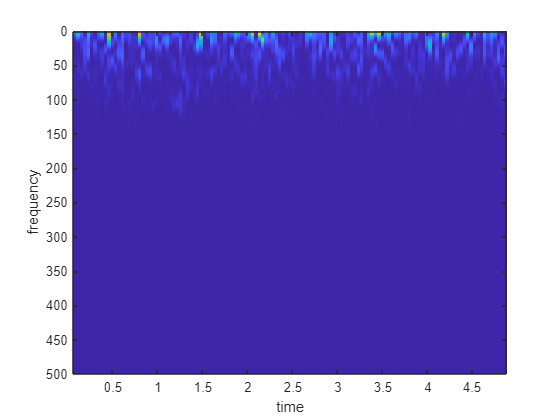

imagesc(t_120,f_120,p_120)
xlabel("time")
ylabel("frequency")

We do the same for data channel 1

[p_1,f_1,t_1] = pspectrum(data_chan_1, fs,"spectrogram")

p_1 = 1.0e+03 *

    0.2560    0.0202    0.0177    0.2690    0.1128    0.0312    0.1471    0.3221    0.1666    0.0706    0.0380    0.5916    0.6657    0.0263    0.0021    0.0731    0.1258    0.1228    0.0169    0.0103    0.3688    0.4250    0.1892    0.2966    0.4406    0.0002    0.0443    0.0274    0.6144    2.5504    3.2198    1.4787    0.0534    0.3637    1.2643    0.4761    0.0265    0.1730    0.5028    0.2900    0.0782    0.0016    0.0047    0.1008    0.0561    0.0012    1.1685    0.3792    0.5382    1.0547
    0.2559    0.0203    0.0180    0.2689    0.1127    0.0313    0.1469    0.3210    0.1665    0.0706    0.0387    0.5902    0.6641    0.0267    0.0023    0.0730    0.1259    0.1228    0.0169    0.0102    0.3685    0.4241    0.1883    0.2962    0.4406    0.0002    0.0446    0.0277    0.6134    2.5454    3.2108    1.4757    0.0537    0.3631    1.2617    0.4751    0.0265    0.1731    0.5015    0.2894    0.0779    0.0017    0.0047    0.1009    0.0561    0.0015    1.1670    0.3791  

f_1 =          0
    0.4888
    0.9775
    1.4663
    1.9550
    2.4438
    2.9326
    3.4213
    3.9101
    4.3988


t_1 =     0.0770
    0.1150
    0.1530
    0.1910
    0.2290
    0.2670
    0.3050
    0.3430
    0.3810
    0.4190


Further plotting the spectrogram of data channel 1 using a waterfall graph:

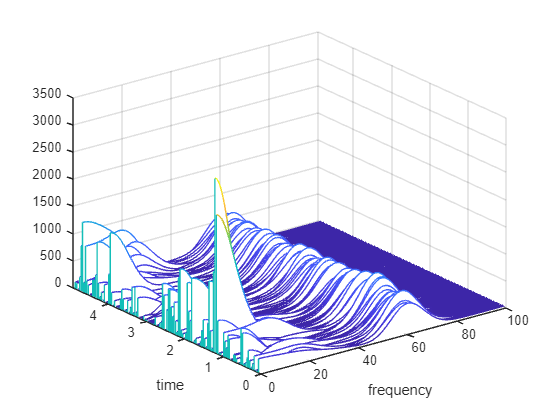

waterfall(f_1,t_1,p_1')
xlabel("frequency")
ylabel("time")
xlim([0,100])
ylim([0,4.925])

wtf = gca

wtf =   Axes with properties:

             XLim: [0 100]
             YLim: [0 4.9250]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


To get the coherence between the two channels, we would want cross sectrum to get that we need the STFT both the channels. Hence computing stft:

[s_1,f_1,t_1] = stft(data_chan_1,fs,Window=hamming(64),OverlapLength=32)

s_1 = 1.0e+03 *

  -0.0035 + 0.0016i   0.0034 + 0.0024i   0.0005 - 0.0036i  -0.0012 + 0.0005i   0.0006 - 0.0005i  -0.0049 + 0.0002i   0.0057 + 0.0024i   0.0020 - 0.0001i  -0.0001 + 0.0015i   0.0024 - 0.0010i   0.0004 - 0.0016i  -0.0038 + 0.0042i  -0.0017 - 0.0003i  -0.0020 - 0.0030i  -0.0010 + 0.0019i   0.0012 + 0.0002i  -0.0056 - 0.0018i  -0.0021 + 0.0040i   0.0035 - 0.0022i  -0.0019 - 0.0014i   0.0018 + 0.0050i   0.0023 - 0.0037i   0.0021 - 0.0003i  -0.0022 + 0.0006i   0.0000 - 0.0002i  -0.0021 - 0.0009i   0.0003 + 0.0014i  -0.0035 - 0.0024i   0.0004 + 0.0014i   0.0011 + 0.0011i  -0.0004 - 0.0015i   0.0019 + 0.0041i   0.0031 - 0.0018i  -0.0019 - 0.0014i   0.0003 + 0.0042i   0.0026 - 0.0036i  -0.0030 - 0.0004i  -0.0006 + 0.0029i  -0.0057 - 0.0041i  -0.0073 + 0.0008i   0.0007 + 0.0027i  -0.0055 - 0.0032i   0.0014 + 0.0052i   0.0053 + 0.0002i   0.0020 - 0.0012i  -0.0005 + 0.0010i   0.0031 - 0.0058i  -0.0006 + 0.0020i  -0.0014 + 0.0019i   0.0010 - 0.0054i
   0.0009 - 0.0006i  -0.0039 - 0

f_1 =  -484.3750
 -468.7500
 -453.1250
 -437.5000
 -421.8750
 -406.2500
 -390.6250
 -375.0000
 -359.3750
 -343.7500


t_1 =     0.0320
    0.0640
    0.0960
    0.1280
    0.1600
    0.1920
    0.2240
    0.2560
    0.2880
    0.3200


[s_120,f_120,t_120] = stft(data_chan_120,fs,Window=hamming(64),OverlapLength=32)

s_120 = 1.0e+03 *

   0.0031 - 0.0039i  -0.0015 + 0.0005i   0.0017 + 0.0032i  -0.0017 - 0.0003i  -0.0012 + 0.0019i   0.0042 - 0.0022i  -0.0005 - 0.0021i   0.0003 + 0.0047i   0.0013 - 0.0003i   0.0006 + 0.0009i  -0.0036 + 0.0015i   0.0004 + 0.0021i  -0.0054 - 0.0025i  -0.0024 + 0.0009i   0.0022 - 0.0015i  -0.0047 + 0.0019i   0.0016 + 0.0033i  -0.0014 - 0.0019i  -0.0054 + 0.0007i   0.0015 + 0.0007i  -0.0005 - 0.0009i   0.0004 + 0.0072i   0.0045 - 0.0014i   0.0018 - 0.0040i  -0.0025 + 0.0018i   0.0002 - 0.0026i  -0.0021 + 0.0020i  -0.0006 + 0.0022i  -0.0004 - 0.0029i  -0.0017 + 0.0009i   0.0025 - 0.0007i   0.0005 - 0.0005i  -0.0004 + 0.0022i   0.0033 - 0.0025i  -0.0056 + 0.0030i   0.0002 + 0.0036i   0.0063 + 0.0003i  -0.0048 - 0.0029i   0.0035 + 0.0050i  -0.0018 - 0.0038i  -0.0030 + 0.0030i   0.0004 + 0.0023i  -0.0012 - 0.0020i   0.0025 + 0.0016i  -0.0037 + 0.0005i  -0.0035 - 0.0004i   0.0055 + 0.0026i  -0.0018 - 0.0027i   0.0001 + 0.0014i   0.0024 - 0.0011i
  -0.0069 + 0.0018i   0.0038 -

f_120 =  -484.3750
 -468.7500
 -453.1250
 -437.5000
 -421.8750
 -406.2500
 -390.6250
 -375.0000
 -359.3750
 -343.7500


t_120 =     0.0320
    0.0640
    0.0960
    0.1280
    0.1600
    0.1920
    0.2240
    0.2560
    0.2880
    0.3200


This gives us the stft of both the spectrums, to get the power spectrum we additionally need delta and T, whcih can be ignored in our calculation of coherence as they would get cancelled.

kappa = s_1.*conj(s_120)./abs(s_1)

kappa = 1.0e+03 *

  -0.0045 - 0.0022i  -0.0009 - 0.0013i  -0.0030 - 0.0021i   0.0015 - 0.0009i  -0.0022 - 0.0005i  -0.0042 - 0.0020i  -0.0013 + 0.0017i  -0.0001 - 0.0047i  -0.0004 + 0.0013i   0.0002 - 0.0011i  -0.0023 + 0.0031i   0.0013 + 0.0017i   0.0057 - 0.0015i   0.0006 + 0.0025i  -0.0023 + 0.0013i  -0.0042 - 0.0028i  -0.0026 + 0.0027i  -0.0010 - 0.0021i  -0.0050 + 0.0024i  -0.0017 - 0.0003i  -0.0010 - 0.0001i  -0.0059 - 0.0041i   0.0047 + 0.0008i  -0.0028 - 0.0033i  -0.0019 + 0.0024i   0.0008 - 0.0025i   0.0016 - 0.0024i  -0.0007 + 0.0022i  -0.0029 + 0.0005i  -0.0007 - 0.0018i   0.0001 - 0.0026i  -0.0002 + 0.0007i  -0.0014 - 0.0017i  -0.0012 - 0.0040i   0.0025 - 0.0058i  -0.0028 - 0.0023i  -0.0063 - 0.0005i  -0.0018 - 0.0053i  -0.0058 + 0.0020i   0.0014 - 0.0040i   0.0022 - 0.0037i  -0.0015 + 0.0018i  -0.0022 - 0.0007i   0.0026 - 0.0015i  -0.0034 + 0.0015i   0.0012 - 0.0034i   0.0004 - 0.0061i  -0.0021 - 0.0025i   0.0011 + 0.0008i   0.0015 - 0.0022i
  -0.0066 + 0.0025i  -0.0027 -

kappa = kappa./abs(s_120)

kappa =   -0.8947 - 0.4467i  -0.5663 - 0.8242i  -0.8141 - 0.5808i   0.8515 - 0.5244i  -0.9726 - 0.2326i  -0.9021 - 0.4316i  -0.6122 + 0.7907i  -0.0129 - 0.9999i  -0.3080 + 0.9514i   0.1449 - 0.9895i  -0.6028 + 0.7979i   0.6045 + 0.7966i   0.9682 - 0.2502i   0.2188 + 0.9758i  -0.8739 + 0.4862i  -0.8307 - 0.5567i  -0.6899 + 0.7239i  -0.4428 - 0.8966i  -0.9025 + 0.4307i  -0.9809 - 0.1945i  -0.9884 - 0.1518i  -0.8261 - 0.5636i   0.9849 + 0.1734i  -0.6500 - 0.7599i  -0.6130 + 0.7901i   0.3139 - 0.9495i   0.5617 - 0.8273i  -0.3200 + 0.9474i  -0.9861 + 0.1660i  -0.3531 - 0.9356i   0.0211 - 0.9998i  -0.2878 + 0.9577i  -0.6339 - 0.7734i  -0.2766 - 0.9610i   0.3932 - 0.9195i  -0.7783 - 0.6279i  -0.9967 - 0.0809i  -0.3195 - 0.9476i  -0.9450 + 0.3270i   0.3284 - 0.9445i   0.5058 - 0.8626i  -0.6355 + 0.7721i  -0.9561 - 0.2929i   0.8587 - 0.5124i  -0.9147 + 0.4041i   0.3419 - 0.9397i   0.0601 - 0.9982i  -0.6350 - 0.7725i   0.7813 + 0.6241i   0.5661 - 0.8243i
  -0.9341 + 0.3571i  -0.6282 - 0.7780i  -

The above value of kappa is our coherence. We now plot coherence against frequency and time

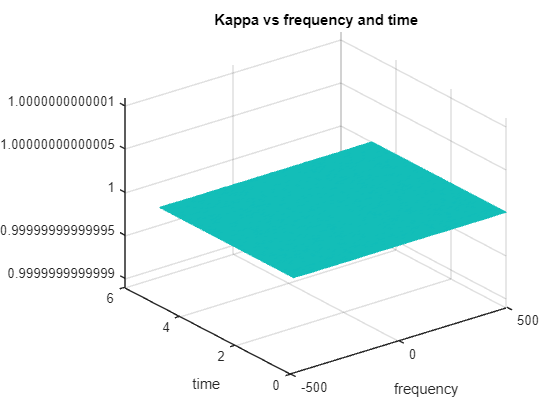

waterfall(f_1,t_1,abs(kappa)')
xlabel("frequency")
ylabel("time")
title("Kappa vs frequency and time")

Kappa values should be one for a single trial!. And it is good that we got what we expected. Now, we have to calculate kappa values for the periods of interest in the same way.

The below is the speech on values during which we would calculate coherence

sp_on = [63239.62877
63245.60922
63251.51378
NaN
63264.55013
63270.04839
63275.14668
63280.46156
63285.71963
63290.35265
63295.11852
63300.31766
63305.51883
63311.19845
63316.30811
63321.92321
63326.90322
63333.30352
63338.34562
63343.88368
63349.11164
63355.14957
63359.74976
63365.89791
63371.25139
63376.87508
NaN
63388.18517
63393.32905
63398.30752
63403.46825
63411.82872
63417.29888
63422.58202
63427.56077
NaN
63437.79217
63442.81187
63447.5633
63452.11734
63461.49503
63466.51501
63471.17012
63476.31085
63481.33452
63485.99056
63490.96485
63539.95872
63545.07201
63550.18931
63555.01076
63559.73704
63564.60806
63569.48788
63574.25001
63579.21248
63584.52541
63589.30703
63594.13151
63598.93722
63604.65239
63610.04237
63615.31722
63620.48619
63625.1997
63629.99699
63635.26969
63640.62522
63645.58447
63650.7937
63655.90722
63661.33137
63666.55328
63671.63772
63676.79489
NaN
63689.08911
63694.55556
63699.77569
63704.81303
63710.28781
63715.5405
63720.81304
NaN
63859.53817
NaN
63869.28783
63874.12969
63879.33929
63884.70302
63889.99049
63894.82833
63899.85042
63905.13752
63909.94874
63998.72663
64003.82685
64008.63292
64013.73542
64019.02002
64023.80581
64029.19232
64034.75815
64039.7467
64044.63752
64049.50066
64054.10834
64059.40821
64064.47537
64070.41881
64075.14998
64084.50246
64089.97908
64095.64184
64100.41553
64105.6297
64110.4722
64116.43543
64121.4
64126.70804
64131.67088
64137.25819
NaN
64147.87647
64152.4911
64161.66833
NaN
64172.26442
64176.93209
64183.38797
64188.24826
64193.12576
64198.32589
64203.38193
64208.46572
64213.67677
64218.88949
64223.75983
64228.80091
64233.63966
64238.7647
64243.65488
64248.60224
64254.09274
]

sp_on = 1.0e+04 *

    6.3240
    6.3246
    6.3252
       NaN
    6.3265
    6.3270
    6.3275
    6.3280
    6.3286
    6.3290


Right now lets calculate the coherence values across trials for the above for an interval of 450ms post speech onset

Consider channel 1 for all the trials.

sxx = 0

sxx = 0

syy = 0

syy = 0

sxy = 0

sxy = 0

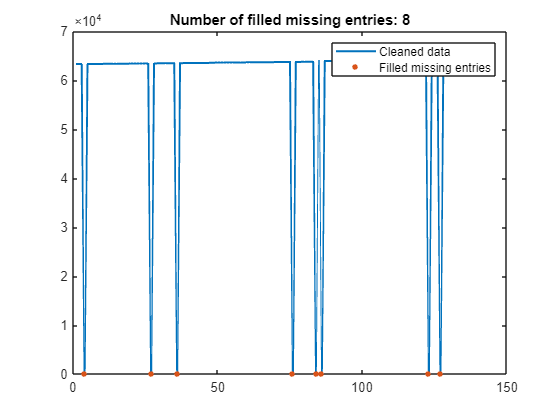

% Fill missing data
[cleanedData,missingIndices] = fillmissing(sp_on,"constant",0);

% Display results
figure

% Plot cleaned data
plot(cleanedData,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices),cleanedData(missingIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))

hold off
legend

clear missingIndices
for i = 1:1:144
    if sp_on(i) ~= 0
        time_duration = sp_on(i) - D_trial_ref.time{i}(1)
        interval = D_trial_ref.time{i}(2) - D_trial_ref.time{i}(1)
        if isnan(interval) == 0 & isnan(time_duration) == 0
            points_start = time_duration/interval
            if points_start+450 < length(D_trial_ref.time{i}) - points_start
                fin_points_1 = D_trial_ref.trial{i}(1,points_start:points_start+450)
                fin_points_120 = D_trial_ref.trial{i}(120,points_start:points_start+450)
                [s_1,f_1,t_1] = stft(fin_points_1,fs,Window=hamming(32),OverlapLength=16)
                [s_120,f_120,t_120] = stft(fin_points_120,fs,Window=hamming(32),OverlapLength=16)
                sxx = sxx + s_1.*conj(s_1)
                syy = syy + s_120.*conj(s_120)
                sxy = sxy + s_1.*conj(s_120)
            end
        end
    end
end

time_duration = 3.0091

interval = 1.0000e-03

points_start = 3.0091e+03

time_duration = 3.0556

interval = 1.0000e-03

points_start = 3.0556e+03

time_duration = 2.7781

interval = 1.0000e-03

points_start = 2.7781e+03

time_duration = NaN

interval = 0.0010

time_duration = 2.5485

interval = 0.0010

points_start = 2.5485e+03

time_duration = 2.6458

interval = 1.0000e-03

points_start = 2.6458e+03

time_duration = 2.6940

interval = 0.0010

points_start = 2.6940e+03

time_duration = 2.7599

interval = 1.0000e-03

points_start = 2.7599e+03

time_duration = 3.0180

interval = 1.0000e-03

points_start = 3.0180e+03

time_duration = 2.7840

interval = 1.0000e-03

points_start = 2.7840e+03

time_duration = 2.7159

interval = 1.0000e-03

points_start = 2.7159e+03

time_duration = 2.8990

interval = 0.0010

points_start = 2.8990e+03

time_duration = 2.4832

interval = 0.0010

points_start = 2.4832e+03

time_duration = 3.1468

interval = 1.0000e-03

points_start = 3.1468e+03

time_duration = 2.7725

interval = 0.0010

points_start = 2.7725e+03

time_duration = 2.9376

interval = 1.0000e-03

points_start = 2.9376e+03

time_duration = 2.9846

interval = 0.0010

points_start = 2.9846e+03

time_duration = 3.2349

interval = 1.0000e-03

points_start = 3.2349e+03

time_duration = 2.8940

interval = 1.0000e-03

points_start = 2.8940e+03

time_duration = 2.8650

interval = 0.0010

points_start = 2.8650e+03

time_duration = 2.9260

interval = 0.0010

points_start = 2.9260e+03

time_duration = 2.6809

interval = 1.0000e-03

points_start = 2.6809e+03

time_duration = 2.7811

interval = 1.0000e-03

points_start = 2.7811e+03

time_duration = 3.1633

interval = 0.0010

points_start = 3.1633e+03

time_duration = 2.8498

interval = 0.0010

points_start = 2.8498e+03

time_duration = 2.9354

interval = 0.0010

points_start = 2.9354e+03

time_duration = NaN

interval = 1.0000e-03

time_duration = 2.5315

interval = 0.0010

points_start = 2.5315e+03

time_duration = 2.6724

interval = 0.0010

points_start = 2.6724e+03

time_duration = 2.7639

interval = 0.0010

points_start = 2.7639e+03

time_duration = 2.9286

interval = 0.0010

points_start = 2.9286e+03

fin_points_1 =   -78.9087  -86.5497  -96.5316 -102.8174  -93.8589  -79.2282  -62.0552  -37.0692  -17.5833   -5.1738    6.1646   12.1406   10.4427    6.1733   -0.4473   -7.4181  -17.2924  -29.5404  -37.7641  -50.5275  -54.4637  -45.3541  -31.7603  -17.6510   -1.6285   10.3576   19.1376   26.0599   26.1646   19.8646   15.8787    6.1285    0.0557   -8.2512  -10.0021  -11.9090  -18.6111  -16.3227   -7.7472    3.8505   18.6784   34.2338   45.0215   48.8024   52.2699   46.8457   31.1068   10.7673  -10.0589  -28.0951


fin_points_120 =   -26.8570  -31.2234  -31.0546  -24.8173  -17.4671  -16.9277  -13.2618   -9.2465  -14.1764  -14.3200  -16.1584  -19.5821  -16.8355  -19.8752  -20.7071  -19.0766  -18.9077  -19.3275  -18.6314  -21.9344  -20.4693  -24.1170  -26.2115  -21.4613  -16.1722  -13.2252  -11.1795  -10.4967  -11.3917   -9.4848  -11.8083  -11.6295  -19.3595  -24.2786  -24.5068  -19.4376  -17.7469  -15.4830  -12.2250   -9.1892   -5.7624   -6.3950   -8.0942  -11.4448   -9.6068   -7.7455  -10.6674  -13.5372  -14.3451  -16.5012


s_1 = 1.0e+02 *

  -0.0468 + 0.0135i  -0.0359 - 0.0207i   0.0275 - 0.0087i  -0.0123 + 0.0183i  -0.0551 - 0.0053i   0.0206 - 0.0021i  -0.0186 + 0.0183i  -0.0196 + 0.0217i  -0.0112 - 0.0196i  -0.0073 + 0.0019i   0.0021 + 0.0064i  -0.0115 - 0.0185i   0.0152 + 0.0198i  -0.0108 + 0.0089i   0.0328 + 0.0043i   0.0164 + 0.0055i  -0.0332 - 0.0059i   0.0477 + 0.0108i   0.0031 + 0.0218i  -0.0466 + 0.0056i  -0.0023 + 0.0062i   0.0344 + 0.0004i  -0.0035 + 0.0079i  -0.0451 - 0.0446i  -0.0004 + 0.0146i  -0.0110 + 0.0141i   0.0107 - 0.0196i
  -0.0113 - 0.0222i   0.0319 + 0.0367i  -0.0324 + 0.0239i  -0.0021 - 0.0629i   0.0421 - 0.0091i  -0.0215 + 0.0358i  -0.0224 - 0.0423i   0.0826 - 0.0569i   0.0423 + 0.0331i  -0.0208 + 0.0286i   0.0153 - 0.0413i   0.0996 + 0.0055i  -0.0093 + 0.0398i  -0.0341 - 0.0266i  -0.0032 - 0.0378i   0.0296 + 0.0164i  -0.0137 + 0.0197i   0.0385 - 0.0435i   0.0371 - 0.0315i  -0.0211 + 0.0122i  -0.0314 - 0.0219i  -0.0020 - 0.0433i   0.0099 + 0.0183i  -0.0306 + 0.0682i  -0.0155 - 0

f_1 =  -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_1 =     0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


s_120 = 1.0e+02 *

  -0.0454 + 0.0039i   0.0551 + 0.0173i  -0.0150 + 0.0044i  -0.0153 + 0.0015i   0.0061 - 0.0054i   0.0076 - 0.0089i  -0.0139 - 0.0039i  -0.0198 - 0.0330i  -0.0047 + 0.0228i  -0.0170 - 0.0196i   0.0026 + 0.0042i  -0.0074 + 0.0000i  -0.0571 - 0.0060i   0.0087 - 0.0172i   0.0330 + 0.0341i   0.0055 + 0.0197i  -0.0042 - 0.0126i  -0.0072 - 0.0039i  -0.0144 + 0.0232i   0.0414 - 0.0266i   0.0232 + 0.0236i   0.0170 + 0.0071i  -0.0349 + 0.0119i   0.0035 + 0.0041i   0.0079 + 0.0243i   0.0030 - 0.0101i   0.0131 + 0.0055i
   0.0182 - 0.0033i  -0.0421 - 0.0194i  -0.0176 - 0.0148i   0.0148 - 0.0260i  -0.0137 + 0.0173i  -0.0425 + 0.0063i  -0.0070 + 0.0122i   0.0340 + 0.0264i   0.0479 + 0.0039i   0.0428 + 0.0308i   0.0206 + 0.0097i   0.0052 + 0.0019i   0.0166 + 0.0176i   0.0091 - 0.0032i  -0.0146 - 0.0362i  -0.0369 - 0.0187i  -0.0008 - 0.0162i   0.0470 - 0.0132i   0.0187 + 0.0113i  -0.0266 + 0.0148i  -0.0052 - 0.0048i  -0.0048 - 0.0413i  -0.0109 - 0.0247i   0.0090 - 0.0170i  -0.0081 -

f_120 =  -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_120 =     0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


sxx = 1.0e+05 *

    0.0002    0.0002    0.0001    0.0000    0.0003    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0002    0.0000    0.0002    0.0000    0.0001    0.0000    0.0004    0.0000    0.0000    0.0000
    0.0001    0.0002    0.0002    0.0004    0.0002    0.0002    0.0002    0.0010    0.0003    0.0001    0.0002    0.0010    0.0002    0.0002    0.0001    0.0001    0.0001    0.0003    0.0002    0.0001    0.0001    0.0002    0.0000    0.0006    0.0001    0.0002    0.0003
    0.0002    0.0004    0.0005    0.0005    0.0008    0.0003    0.0006    0.0004    0.0001    0.0002    0.0004    0.0005    0.0005    0.0001    0.0002    0.0001    0.0002    0.0006    0.0001    0.0003    0.0002    0.0005    0.0003    0.0005    0.0008    0.0001    0.0002
    0.0003    0.0003    0.0002    0.0002    0.0004    0.0002    0.0004    0.0000    0.0004    0.0001    0.0002    0.0000    0.0001    0.0001    0.0001    0.0002    0.0001

syy = 1.0e+05 *

    0.0002    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0003    0.0000    0.0002    0.0000    0.0000    0.0000    0.0001    0.0002    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000
    0.0000    0.0002    0.0001    0.0001    0.0000    0.0002    0.0000    0.0002    0.0002    0.0003    0.0001    0.0000    0.0001    0.0000    0.0002    0.0002    0.0000    0.0002    0.0000    0.0001    0.0000    0.0002    0.0001    0.0000    0.0001    0.0000    0.0000
    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0001    0.0001    0.0002    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0001    0.0005    0.0000    0.0004    0.0003    0.0001    0.0003    0.0003    0.0001    0.0002
    0.0010    0.0001    0.0000    0.0003    0.0006    0.0004    0.0006    0.0003    0.0004    0.0002    0.0003    0.0005    0.0004    0.0005    0.0002    0.0004    0.0003

sxy = 1.0e+05 *

   0.0002 - 0.0000i  -0.0002 - 0.0001i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0001i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0001 - 0.0001i  -0.0000 - 0.0000i   0.0001 - 0.0001i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0002 - 0.0001i   0.0000 + 0.0000i   0.0001 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i  -0.0002 - 0.0001i   0.0000 - 0.0001i   0.0002 - 0.0001i  -0.0001 - 0.0001i   0.0001 - 0.0001i  -0.0000 + 0.0001i   0.0001 - 0.0004i   0.0002 + 0.0001i  -0.0000 + 0.0002i  -0.0000 - 0.0001i   0.0001 - 0.0000i   0.0001 + 0.0001i  -0.0000 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0000 - 0.0000i   0.0002 - 0.0002i   0.0000 - 0.0001i   0.0001 - 0.0000i   0.0000 - 0.0000i   0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i   0.0001 - 0

time_duration = 2.4841

interval = 0.0010

points_start = 2.4841e+03

time_duration = 2.8742

interval = 1.0000e-03

points_start = 2.8742e+03

time_duration = 2.7394

interval = 0.0010

points_start = 2.7394e+03

time_duration = 2.7201

interval = 0.0010

points_start = 2.7201e+03

time_duration = NaN

interval = 1.0000e-03

time_duration = 2.9215

interval = 0.0010

points_start = 2.9215e+03

time_duration = 2.7562

interval = 1.0000e-03

points_start = 2.7562e+03

time_duration = 2.6727

interval = 1.0000e-03

points_start = 2.6727e+03

time_duration = 2.4927

interval = 0.0010

points_start = 2.4927e+03

fin_points_1 =   -34.1824  -45.0215  -42.2620  -35.3420  -19.3253   -2.5359    9.5380   16.5544   21.8037   29.2514   27.7783   21.2311   14.6045    8.4961   -0.5851  -11.4046  -17.4362  -27.6278  -31.0228  -23.9024  -17.0851   -3.9451   14.8016   22.2877   29.9767   37.9328   41.6277   34.9901   24.8105   11.8668    4.8689   -8.5078  -19.9463  -28.5288  -41.8608  -42.3335  -35.9803  -25.9474   -8.3778    9.4015   16.6008   22.3642   32.4726   36.4272   32.3012   24.5647   12.3661    4.6511  -10.1105  -16.9431


fin_points_120 =    48.0779   57.3368   66.1815   68.4577   71.5535   72.8428   67.2081   62.0325   57.0531   50.6056   41.9158   24.3588    9.3313   -0.5624   -7.9686  -11.5959  -12.8178  -10.4960   -5.6636   -8.3514  -12.3665  -10.2500   -6.1269   -9.4786  -11.3573  -12.1275  -13.6180  -19.7250  -21.5253  -19.3942  -16.0042  -15.3455  -15.8074  -18.4871  -11.9945    2.6698   12.4273   18.4644   18.2051   12.1074    1.5038  -10.5784  -13.0184  -13.1263  -14.3096  -17.1100  -26.8226  -36.7257  -42.9233  -43.2579


s_1 = 1.0e+02 *

  -0.0139 + 0.0216i  -0.0061 - 0.0428i   0.0150 + 0.0196i  -0.0274 + 0.0100i   0.0037 - 0.0068i  -0.0098 - 0.0171i  -0.0245 + 0.0276i  -0.0233 - 0.0161i   0.0050 - 0.0089i  -0.0157 + 0.0164i  -0.0329 + 0.0057i   0.0098 - 0.0207i   0.0270 + 0.0146i  -0.0402 - 0.0034i   0.0153 - 0.0143i   0.0145 - 0.0119i   0.0059 + 0.0177i   0.0045 - 0.0064i   0.0155 - 0.0160i  -0.0154 + 0.0018i   0.0222 + 0.0030i   0.0333 + 0.0112i  -0.0252 + 0.0035i   0.0050 - 0.0131i   0.0253 + 0.0011i  -0.0030 - 0.0251i  -0.0244 - 0.0098i
   0.0114 + 0.0064i  -0.0329 + 0.0431i  -0.0578 - 0.0594i   0.0644 - 0.0280i   0.0095 + 0.0446i  -0.0513 + 0.0111i   0.0103 - 0.0551i   0.0931 + 0.0222i  -0.0157 + 0.0399i  -0.0432 - 0.0257i   0.0638 - 0.0365i   0.0491 + 0.0521i  -0.0520 + 0.0089i   0.0318 - 0.0356i   0.0555 + 0.0290i  -0.0173 + 0.0625i  -0.0599 - 0.0277i   0.0505 - 0.0324i   0.0368 + 0.0667i  -0.0559 + 0.0130i  -0.0132 - 0.0480i   0.0572 - 0.0001i  -0.0083 + 0.0311i  -0.0836 - 0.0062i  -0.0162 - 0

f_1 =  -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_1 =     0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


s_120 = 1.0e+02 *

   0.0136 + 0.0108i   0.0046 - 0.0194i  -0.0090 + 0.0141i   0.0104 - 0.0150i  -0.0035 + 0.0126i   0.0059 + 0.0236i  -0.0593 - 0.0125i   0.0256 - 0.0151i   0.0040 + 0.0116i   0.0129 - 0.0104i   0.0019 - 0.0060i   0.0013 + 0.0116i   0.0052 - 0.0062i   0.0554 + 0.0018i   0.0094 + 0.0184i  -0.0179 - 0.0142i   0.0178 - 0.0106i  -0.0224 - 0.0107i  -0.0283 - 0.0141i  -0.0277 - 0.0149i  -0.0140 + 0.0207i   0.0049 + 0.0168i   0.0393 + 0.0132i   0.0650 - 0.0059i  -0.0719 - 0.0135i  -0.0373 - 0.0230i   0.0021 + 0.0272i
   0.0103 + 0.0031i   0.0046 + 0.0250i  -0.0191 - 0.0307i   0.0001 - 0.0126i   0.0173 + 0.0014i  -0.0388 - 0.0358i   0.0228 - 0.0146i   0.0050 + 0.0370i  -0.0041 + 0.0068i  -0.0218 + 0.0143i   0.0131 - 0.0149i   0.0338 + 0.0060i   0.0025 + 0.0025i  -0.0194 + 0.0075i  -0.0105 - 0.0157i   0.0067 + 0.0308i  -0.0367 + 0.0278i  -0.0205 + 0.0116i  -0.0167 + 0.0002i   0.0235 + 0.0148i   0.0123 - 0.0267i   0.0208 - 0.0365i   0.0218 - 0.0052i  -0.0076 + 0.0119i   0.0103 +

f_120 =  -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_120 =     0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


sxx = 1.0e+05 *

    0.0003    0.0004    0.0001    0.0001    0.0003    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0002    0.0001    0.0004    0.0001    0.0001    0.0001
    0.0001    0.0005    0.0008    0.0009    0.0004    0.0005    0.0005    0.0019    0.0005    0.0004    0.0007    0.0015    0.0004    0.0004    0.0005    0.0005    0.0005    0.0007    0.0008    0.0004    0.0004    0.0005    0.0001    0.0013    0.0003    0.0008    0.0005
    0.0005    0.0007    0.0012    0.0014    0.0010    0.0005    0.0009    0.0009    0.0003    0.0002    0.0009    0.0007    0.0007    0.0005    0.0002    0.0004    0.0010    0.0008    0.0008    0.0006    0.0004    0.0008    0.0005    0.0006    0.0016    0.0004    0.0004
    0.0007    0.0010    0.0013    0.0005    0.0004    0.0009    0.0008    0.0007    0.0007    0.0005    0.0002    0.0003    0.0002    0.0002    0.0004    0.0006    0.0004

syy = 1.0e+05 *

    0.0002    0.0004    0.0001    0.0001    0.0000    0.0001    0.0004    0.0002    0.0001    0.0001    0.0000    0.0000    0.0003    0.0003    0.0003    0.0001    0.0001    0.0001    0.0002    0.0003    0.0002    0.0001    0.0003    0.0004    0.0006    0.0002    0.0001
    0.0000    0.0003    0.0002    0.0001    0.0001    0.0005    0.0001    0.0003    0.0002    0.0003    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0002    0.0003    0.0001    0.0002    0.0001    0.0003    0.0001    0.0001    0.0001    0.0000    0.0001
    0.0003    0.0001    0.0003    0.0001    0.0001    0.0001    0.0005    0.0002    0.0003    0.0003    0.0003    0.0001    0.0002    0.0002    0.0001    0.0001    0.0004    0.0004    0.0006    0.0002    0.0007    0.0005    0.0001    0.0008    0.0004    0.0007    0.0004
    0.0013    0.0004    0.0000    0.0005    0.0009    0.0004    0.0011    0.0006    0.0010    0.0010    0.0009    0.0006    0.0008    0.0010    0.0005    0.0005    0.0004

sxy = 1.0e+05 *

   0.0002 + 0.0000i  -0.0002 - 0.0001i  -0.0000 - 0.0000i  -0.0000 - 0.0001i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0001 - 0.0002i  -0.0001 - 0.0002i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0001i  -0.0002 - 0.0000i   0.0001 - 0.0001i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0002 - 0.0001i  -0.0000 - 0.0000i   0.0001 - 0.0001i  -0.0001 + 0.0000i   0.0000 - 0.0001i  -0.0001 + 0.0000i   0.0001 + 0.0001i  -0.0000 + 0.0000i
   0.0000 - 0.0000i  -0.0001 + 0.0000i   0.0003 - 0.0002i   0.0002 - 0.0000i  -0.0001 + 0.0000i   0.0003 - 0.0004i   0.0001 - 0.0001i   0.0003 - 0.0007i   0.0002 + 0.0001i   0.0001 + 0.0003i   0.0001 - 0.0001i   0.0003 + 0.0001i   0.0000 + 0.0001i  -0.0001 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0001 + 0.0002i   0.0001 - 0.0001i  -0.0000 - 0.0002i  -0.0000 + 0.0001i   0.0001 - 0.0001i   0.0003 + 0.0002i  -0.0001 + 0.0001i  -0.0001 + 0.0001i  -0.0000 - 0

time_duration = 2.8284

interval = 0.0010

points_start = 2.8284e+03

time_duration = 2.6694

interval = 1.0000e-03

points_start = 2.6694e+03

time_duration = 2.5935

interval = 1.0000e-03

points_start = 2.5935e+03

time_duration = 2.6362

interval = 1.0000e-03

points_start = 2.6362e+03

time_duration = 2.8379

interval = 1.0000e-03

points_start = 2.8379e+03

time_duration = 2.7619

interval = 0.0010

points_start = 2.7619e+03

time_duration = 2.6832

interval = 0.0010

points_start = 2.6832e+03

fin_points_1 =    10.1941   19.6481   32.2436   44.3021   48.3243   53.5447   56.3090   46.9240   39.2731   26.8731   18.8986    6.5284   -1.8659   -7.7177  -17.0833  -15.6116   -8.9436   -1.3280   12.8016   24.7841   32.0913   33.2829   40.6830   36.5075   26.0674   13.9030   -0.8989   -9.8841  -24.0579  -27.6412  -33.2670  -42.8296  -40.0615  -35.3905  -28.1789  -15.3271   -7.1731   -2.6618    1.9295    6.4078    5.1465    2.3487   -3.1839   -7.5482  -12.2345  -17.3272  -17.4282  -23.6321  -25.5128  -17.3871


fin_points_120 =   -15.5284   -8.8215   -3.8625   -1.2524    1.3490    3.7782    8.7297    6.2142    3.2781    2.2405    4.0139   -0.1618   -5.6135  -14.9839  -27.8268  -31.2063  -35.9765  -39.1036  -34.5924  -30.7039  -31.3100  -30.1968  -27.8568  -24.0575  -22.6176  -25.3748  -31.2192  -37.0094  -37.7819  -33.5337  -26.8048  -19.5843  -15.2263  -19.0919  -20.4514  -19.5380  -19.9107  -21.6968  -26.1494  -32.3594  -37.1521  -38.9734  -41.7911  -44.4829  -44.0954  -45.2835  -42.5929  -38.5280  -25.4742  -13.8506


s_1 = 1.0e+02 *

  -0.0001 - 0.0011i   0.0233 + 0.0108i  -0.0321 + 0.0075i  -0.0093 - 0.0202i   0.0284 - 0.0057i  -0.0244 - 0.0049i  -0.0088 - 0.0405i   0.0110 + 0.0132i   0.0036 + 0.0419i  -0.0250 - 0.0112i   0.0320 + 0.0008i  -0.0124 - 0.0052i  -0.0328 + 0.0150i   0.0163 - 0.0234i   0.0109 + 0.0296i  -0.0194 - 0.0106i  -0.0203 + 0.0040i   0.0276 - 0.0061i  -0.0262 + 0.0267i  -0.0491 - 0.0169i   0.0112 + 0.0014i   0.0314 + 0.0052i   0.0095 - 0.0163i   0.0113 + 0.0057i  -0.0024 + 0.0081i  -0.0026 - 0.0015i   0.0012 + 0.0116i
  -0.0168 - 0.0579i   0.0515 - 0.0271i  -0.0044 + 0.0233i  -0.0351 + 0.0270i  -0.0042 - 0.0087i   0.0211 + 0.0357i  -0.0429 + 0.0656i  -0.0304 - 0.0562i   0.0091 - 0.0507i  -0.0068 + 0.0195i  -0.0654 + 0.0070i   0.0170 - 0.0495i   0.0697 + 0.0117i  -0.0426 + 0.0536i  -0.0341 - 0.0619i   0.0333 - 0.0391i   0.0105 + 0.0362i  -0.0467 + 0.0077i  -0.0063 - 0.0720i   0.0676 - 0.0004i   0.0266 + 0.0678i  -0.0052 - 0.0188i   0.0332 + 0.0005i   0.0102 + 0.0327i  -0.0177 + 0

f_1 =  -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_1 =     0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


s_120 = 1.0e+02 *

   0.0208 - 0.0140i  -0.0121 - 0.0004i  -0.0150 - 0.0269i  -0.0369 + 0.0132i  -0.0023 - 0.0016i   0.0183 - 0.0154i   0.0188 - 0.0073i   0.0009 + 0.0088i  -0.0054 - 0.0138i   0.0299 + 0.0013i   0.0051 + 0.0067i  -0.0455 + 0.0013i   0.0391 - 0.0021i  -0.0027 - 0.0073i  -0.0285 + 0.0019i   0.0034 - 0.0053i  -0.0039 + 0.0037i  -0.0113 + 0.0084i  -0.0050 - 0.0067i   0.0339 + 0.0028i  -0.0345 - 0.0011i   0.0135 - 0.0137i   0.0274 + 0.0203i   0.0074 + 0.0038i   0.0061 - 0.0250i   0.0056 + 0.0138i  -0.0125 + 0.0119i
  -0.0267 - 0.0121i   0.0187 + 0.0072i  -0.0005 + 0.0409i  -0.0053 - 0.0081i   0.0220 - 0.0048i  -0.0006 + 0.0338i  -0.0445 + 0.0126i  -0.0026 - 0.0268i   0.0304 + 0.0301i  -0.0071 + 0.0333i  -0.0314 - 0.0249i   0.0004 - 0.0205i  -0.0346 - 0.0006i   0.0274 + 0.0181i   0.0278 - 0.0152i   0.0323 - 0.0074i   0.0003 + 0.0498i  -0.0139 - 0.0140i   0.0283 - 0.0277i   0.0053 + 0.0189i  -0.0220 + 0.0137i  -0.0099 - 0.0043i   0.0289 - 0.0008i  -0.0045 + 0.0191i  -0.0439 -

f_120 =  -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_120 =     0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


sxx = 1.0e+05 *

    0.0003    0.0004    0.0003    0.0002    0.0004    0.0001    0.0004    0.0002    0.0002    0.0001    0.0002    0.0001    0.0003    0.0003    0.0003    0.0001    0.0002    0.0003    0.0002    0.0005    0.0001    0.0003    0.0001    0.0004    0.0001    0.0001    0.0001
    0.0004    0.0009    0.0009    0.0011    0.0004    0.0006    0.0012    0.0023    0.0007    0.0004    0.0012    0.0018    0.0009    0.0009    0.0010    0.0008    0.0006    0.0009    0.0013    0.0008    0.0009    0.0006    0.0003    0.0014    0.0003    0.0012    0.0006
    0.0014    0.0013    0.0013    0.0016    0.0011    0.0010    0.0015    0.0015    0.0008    0.0004    0.0016    0.0011    0.0016    0.0011    0.0006    0.0006    0.0015    0.0011    0.0010    0.0014    0.0011    0.0015    0.0005    0.0007    0.0019    0.0008    0.0008
    0.0010    0.0021    0.0018    0.0007    0.0007    0.0011    0.0010    0.0010    0.0012    0.0008    0.0007    0.0005    0.0005    0.0007    0.0007    0.0013    0.0005

syy = 1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000
    0.0002    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001

sxy = 1.0e+05 *

   0.0002 - 0.0000i  -0.0002 - 0.0001i  -0.0000 - 0.0001i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0000i   0.0001 - 0.0003i  -0.0001 - 0.0002i  -0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0002 - 0.0000i  -0.0002 - 0.0000i   0.0001 - 0.0002i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0001 + 0.0000i   0.0000 - 0.0000i  -0.0003 - 0.0002i  -0.0001 - 0.0000i   0.0001 - 0.0000i  -0.0001 - 0.0000i   0.0000 - 0.0001i  -0.0002 + 0.0000i   0.0000 + 0.0001i  -0.0000 + 0.0000i
   0.0001 + 0.0001i  -0.0000 - 0.0001i   0.0004 - 0.0001i   0.0002 - 0.0001i  -0.0001 - 0.0000i   0.0004 - 0.0004i   0.0003 - 0.0003i   0.0004 - 0.0008i   0.0001 - 0.0000i   0.0001 + 0.0003i   0.0003 - 0.0002i   0.0004 + 0.0002i  -0.0002 + 0.0001i  -0.0001 + 0.0002i   0.0000 - 0.0001i   0.0002 - 0.0000i   0.0003 + 0.0002i   0.0002 - 0.0002i   0.0002 - 0.0004i  -0.0000 - 0.0000i   0.0002 - 0.0003i   0.0003 + 0.0002i   0.0000 + 0.0001i  -0.0000 + 0.0001i   0.0001 - 0

time_duration = 3.0131

interval = 1.0000e-03

points_start = 3.0131e+03

time_duration = 2.6274

interval = 0.0010

points_start = 2.6274e+03

time_duration = 2.7847

interval = 1.0000e-03

points_start = 2.7847e+03

time_duration = 2.7271

interval = 0.0010

points_start = 2.7271e+03

time_duration = 2.6224

interval = 1.0000e-03

points_start = 2.6224e+03

time_duration = 2.6204

interval = 1.0000e-03

points_start = 2.6204e+03

time_duration = 2.7852

interval = 0.0010

points_start = 2.7852e+03

time_duration = 2.6374

interval = 1.0000e-03

points_start = 2.6374e+03

time_duration = 2.7758

interval = 1.0000e-03

points_start = 2.7758e+03

time_duration = 3.0308

interval = 1.0000e-03

points_start = 3.0308e+03

time_duration = 2.7354

interval = 0.0010

points_start = 2.7354e+03

time_duration = 2.9059

interval = 0.0010

points_start = 2.9059e+03

time_duration = 2.5346

interval = 1.0000e-03

points_start = 2.5346e+03

time_duration = 2.9608

interval = 1.0000e-03

points_start = 2.9608e+03

time_duration = 2.7817

interval = 1.0000e-03

points_start = 2.7817e+03

time_duration = 2.9186

interval = 1.0000e-03

points_start = 2.9186e+03

time_duration = 2.9136

interval = 1.0000e-03

points_start = 2.9136e+03

time_duration = 2.7711

interval = 1.0000e-03

points_start = 2.7711e+03

time_duration = 2.5284

interval = 1.0000e-03

points_start = 2.5284e+03

time_duration = 2.5471

interval = 1.0000e-03

points_start = 2.5471e+03

time_duration = 2.8006

interval = 1.0000e-03

points_start = 2.8006e+03

time_duration = 2.6628

interval = 1.0000e-03

points_start = 2.6628e+03

time_duration = 3.0251

interval = 0.0010

points_start = 3.0251e+03

time_duration = 2.7546

interval = 1.0000e-03

points_start = 2.7546e+03

time_duration = 2.9417

interval = 0.0010

points_start = 2.9417e+03

time_duration = 2.7536

interval = 1.0000e-03

points_start = 2.7536e+03

time_duration = 2.6231

interval = 0.0010

points_start = 2.6231e+03

time_duration = 2.7583

interval = 1.0000e-03

points_start = 2.7583e+03

time_duration = NaN

interval = 1.0000e-03

time_duration = 2.6755

interval = 1.0000e-03

points_start = 2.6755e+03

time_duration = 2.9639

interval = 1.0000e-03

points_start = 2.9639e+03

time_duration = 2.6811

interval = 0.0010

points_start = 2.6811e+03

time_duration = 2.7244

interval = 0.0010

points_start = 2.7244e+03

time_duration = 3.0752

interval = 1.0000e-03

points_start = 3.0752e+03

time_duration = 2.6929

interval = 1.0000e-03

points_start = 2.6929e+03

time_duration = 2.9734

interval = 1.0000e-03

points_start = 2.9734e+03

time_duration = NaN

interval = 0.0010

time_duration = 2.8935

interval = 1.0000e-03

points_start = 2.8935e+03

time_duration = NaN

interval = 1.0000e-03

time_duration = 2.4882

interval = 1.0000e-03

points_start = 2.4882e+03

time_duration = 2.6441

interval = 1.0000e-03

points_start = 2.6441e+03

time_duration = 2.7817

interval = 1.0000e-03

points_start = 2.7817e+03

time_duration = 2.8814

interval = 0.0010

points_start = 2.8814e+03

time_duration = 2.8249

interval = 1.0000e-03

points_start = 2.8249e+03

time_duration = 2.3727

interval = 1.0000e-03

points_start = 2.3727e+03

time_duration = 2.6268

interval = 0.0010

points_start = 2.6268e+03

time_duration = 2.6269

interval = 1.0000e-03

points_start = 2.6269e+03

time_duration = 2.4991

interval = 1.0000e-03

points_start = 2.4991e+03

fin_points_1 =    30.3861   46.5629   55.3436   58.6727   62.6465   58.3811   48.6968   35.9211   20.6318    7.4779   -0.2087   -3.4451  -12.9101  -17.1655  -11.5336   -7.4511    2.3003   19.1538   32.5603   39.9345   45.5875   48.0727   40.2386   29.1991   15.7216    4.5334   -5.9324  -14.0349  -17.9220  -26.4377  -29.0345  -20.3065  -13.3266   -4.5456    4.8102   11.1549   17.6134   24.6248   32.0712   30.7206   23.8229   17.1485   13.5250   11.4781   10.0671    7.3092    0.1261    0.5462    0.1526    5.2308


fin_points_120 =   -18.3323  -20.0102  -20.8494  -20.0865  -18.3126  -14.5856  -13.0771  -16.5268  -18.2270  -14.4888  -11.1938   -5.6249   -2.0257    2.0426    4.2738    1.7328   -1.7206   -1.8045    0.9951    3.7419    5.7512    7.5659    4.6464    1.7032    1.2592   -6.9435  -22.2291  -32.8535  -43.7775  -52.6717  -50.8899  -46.5541  -41.0651  -33.7360  -27.6785  -16.0879   -9.7402   -6.3184   -1.5088   -1.6405   -3.7097   -9.3798  -13.3838  -16.2929  -20.2896  -20.7290  -24.1355  -21.3039  -14.8153   -7.8022


s_1 = 32×27
   1.9010 - 0.3609i  -0.6133 + 0.9996i   1.2352 + 2.1829i   4.2417 + 0.7084i  -2.2580 - 0.9738i  -3.5080 + 0.3094i   0.4056 + 2.5703i   5.0241 + 2.7506i  -0.6488 - 2.1180i  -0.8892 + 1.8309i   1.7015 + 0.7674i  -1.5758 - 2.6809i  -1.4896 + 0.0702i  -0.8117 + 1.8600i   0.5649 - 1.4530i  -0.2437 - 0.4485i   1.9259 + 1.5759i   0.2798 + 0.2615i   5.2675 - 0.2566i   1.5749 - 0.1031i  -2.3700 - 0.6768i  -1.5918 - 2.2151i   0.1074 + 1.2866i  -2.0005 - 0.7860i  -1.0063 + 0.2872i   1.4298 + 1.8194i   1.0122 - 1.1964i
   4.0626 + 1.3516i  -2.1595 - 0.2206i  -1.3088 - 6.5804i   6.4960 - 0.9557i   2.0091 + 5.5797i  -7.8218 - 2.1152i  -0.8841 - 8.6696i   6.2371 - 1.9814i  -1.7607 + 3.1161i  -6.1627 - 4.2222i   1.6163 - 1.8712i   4.9957 + 4.9578i  -4.7440 + 0.4227i  -6.3388 - 5.2195i   0.3319 + 1.5592i   1.3366 + 2.2596i  -4.0504 - 2.6421i   5.1980 - 3.1702i   3.7692 + 4.6739i  -4.3785 + 2.0137i   0.8621 - 1.6124i   5.9656 + 2.3010i  -1.2903 + 3.8735i  -4.7537 - 0.7021i   1.4035 - 3.9669

f_1 = 32×1
 -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_1 = 27×1
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


s_120 = 32×27
   1.6422 + 0.8737i   1.5594 + 0.2399i  -0.6814 + 0.1047i   1.7715 + 2.2296i   2.7782 - 1.1659i   1.5623 + 2.0486i  -2.8285 + 1.8290i  -0.1524 - 1.0404i  -0.1247 + 0.3874i   2.6057 + 1.5772i  -2.9160 - 3.4041i  -0.8251 - 0.4312i   1.7855 + 1.4171i  -0.1706 - 1.0743i   2.5476 + 1.0603i  -4.7326 + 0.5106i  -1.4281 + 2.0824i   3.2361 - 2.8867i   1.3451 + 5.1393i  -0.6666 - 3.2622i   0.8452 - 0.2006i  -2.6247 - 0.2293i  -2.3609 + 0.0123i   1.3853 + 0.6187i  -1.8774 + 1.1200i   2.4697 - 1.1832i   0.5791 - 1.0703i
   2.2170 - 0.2634i  -1.2134 + 1.3423i  -3.3378 - 3.5316i  -2.4855 - 2.3812i   0.7115 - 0.4213i  -0.9166 - 1.5892i   2.6306 - 3.6515i  -0.5991 - 0.2031i  -0.4576 + 1.2275i   1.6311 + 0.1655i  -2.0145 + 2.2820i  -3.9390 + 0.6057i  -0.8767 + 0.1675i   2.2096 - 2.2157i   2.6153 - 0.5397i   4.6594 + 0.9248i  -0.1581 - 2.9620i   0.6054 + 0.7727i   0.1816 - 2.3615i  -4.6136 + 0.1518i  -0.3701 + 0.0316i   2.7596 - 0.0347i   0.7459 + 2.0177i  -2.4493 - 0.8874i  -1.2585 - 3.92

f_120 = 32×1
 -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_120 = 27×1
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


sxx = 32×27
1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0002    0.0003    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0000    0.0002    0.0000    0.0001    0.0001
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0000    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0002    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    

syy = 32×27
1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0002    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0002    

sxy = 32×27
1.0e+05 *

   0.0003 - 0.0000i  -0.0002 - 0.0001i  -0.0000 - 0.0002i   0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0001 + 0.0001i   0.0002 - 0.0004i  -0.0001 - 0.0001i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0003 - 0.0000i  -0.0003 - 0.0000i   0.0001 - 0.0003i   0.0000 + 0.0000i   0.0000 - 0.0001i  -0.0001 + 0.0000i   0.0001 - 0.0003i  -0.0003 - 0.0001i  -0.0001 - 0.0000i   0.0002 + 0.0000i  -0.0001 - 0.0001i  -0.0000 - 0.0001i  -0.0001 + 0.0000i   0.0001 + 0.0001i   0.0000 + 0.0000i
   0.0002 + 0.0001i  -0.0000 - 0.0000i   0.0007 + 0.0000i   0.0001 + 0.0001i  -0.0001 + 0.0000i   0.0005 - 0.0005i   0.0006 - 0.0006i   0.0004 - 0.0008i   0.0002 - 0.0000i   0.0000 + 0.0003i   0.0002 - 0.0002i   0.0002 - 0.0001i  -0.0002 + 0.0001i  -0.0002 - 0.0000i   0.0000 - 0.0001i   0.0003 + 0.0001i   0.0004 + 0.0001i   0.0002 - 0.0003i   0.0001 - 0.0003i   0.0002 - 0.0001i   0.0002 - 0.0003i   0.0005 + 0.0003i   0.0001 + 0.0001i   0.0001 + 0.0001i   0.00

time_duration = 2.5820

interval = 1.0000e-03

points_start = 2.5820e+03

time_duration = 2.6582

interval = 0.0010

points_start = 2.6582e+03

time_duration = 2.7713

interval = 0.0010

points_start = 2.7713e+03

time_duration = 3.0008

interval = 0.0010

points_start = 3.0008e+03

time_duration = 2.8684

interval = 0.0010

points_start = 2.8684e+03

time_duration = 2.8872

interval = 0.0010

points_start = 2.8872e+03

time_duration = 2.7977

interval = 1.0000e-03

points_start = 2.7977e+03

time_duration = 2.5095

interval = 1.0000e-03

points_start = 2.5095e+03

time_duration = 2.8441

interval = 1.0000e-03

points_start = 2.8441e+03

time_duration = 2.5339

interval = 0.0010

points_start = 2.5339e+03

time_duration = 2.6830

interval = 0.0010

points_start = 2.6830e+03

time_duration = 2.5787

interval = 1.0000e-03

points_start = 2.5787e+03

time_duration = 2.8766

interval = 0.0010

points_start = 2.8766e+03

time_duration = 2.7607

interval = 1.0000e-03

points_start = 2.7607e+03

time_duration = 2.8662

interval = 0.0010

points_start = 2.8662e+03

time_duration = 2.6033

interval = 1.0000e-03

points_start = 2.6033e+03

fin_points_1 = 1×451
   60.1999   67.4439   68.8472   61.0569   53.9610   43.0328   34.2057   23.6801   16.9052   11.2435    5.9841   13.0110   23.8145   36.5965   60.8919   78.5220   87.5875   92.8637   97.9202   90.6956   79.0342   65.1388   49.8577   36.3435   23.2041   19.4001    7.6709   -1.4477    1.4504    9.0413


fin_points_120 = 1×451
   17.8352   26.2965   30.0121   29.5436   24.6450   22.3424   21.0903   15.3424   11.8632   10.4008    8.4523   12.6609   16.7373   17.4929   15.9485   12.5861   13.2098   15.5460   16.4171   14.7343   15.7599   13.9107   14.2938   15.0039   15.9814   16.5507   16.3168   17.8146   17.5104    8.0188


s_1 = 32×27
  -3.1278 - 2.0052i   7.0516 + 0.8155i   0.3847 + 1.2358i  -0.8859 + 0.5171i   2.6428 - 1.5459i   1.0165 - 1.4082i  -1.2278 - 0.1835i   1.0846 + 0.1726i  -0.3129 + 0.0814i  -1.1229 - 0.2410i   0.3776 - 0.2267i   0.2351 + 1.0170i  -0.2054 - 2.2856i   2.1280 - 0.2893i  -0.1880 + 2.8830i  -4.2592 - 1.0628i   1.0827 - 1.6271i   2.5058 + 2.1361i  -5.1298 + 1.6162i  -0.6966 - 1.4561i  -0.0521 + 0.4569i  -2.7486 + 1.5086i   2.0859 - 3.1975i   2.5596 + 3.8320i  -0.2332 - 1.1265i  -0.6556 + 0.1582i   2.9220 - 0.4209i
   6.0894 - 0.6093i   3.8666 + 3.0484i  -1.0461 + 1.3621i   0.8067 - 4.5811i   2.6936 + 3.5396i  -0.1474 + 7.0539i  -5.5037 - 2.3840i   4.9772 - 4.7248i   7.4427 + 5.5041i  -5.2182 + 2.4165i  -1.9775 - 4.3917i   5.5910 + 1.4152i  -2.3864 + 7.0271i  -9.2079 - 2.8429i   3.8284 - 7.5494i   4.8410 + 4.9312i  -5.2957 + 2.2448i  -3.3935 - 6.7292i   7.8243 - 4.3399i   2.2442 + 4.8226i  -4.5331 + 0.0951i   3.0028 - 4.2990i   4.2726 + 2.4349i  -3.6437 + 2.1682i  -1.8046 - 3.8877

f_1 = 32×1
 -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_1 = 27×1
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


s_120 = 32×27
  -1.1929 + 1.7638i  -0.2353 - 0.9765i  -0.4327 - 1.5331i   0.8547 + 0.4163i   0.5519 - 0.4194i  -3.3101 - 0.0789i  -1.5045 - 0.5123i  -0.0941 + 0.7207i  -0.6769 - 1.4280i  -1.4647 - 1.6326i  -2.3938 + 0.1853i  -0.1056 + 2.7954i   3.3530 - 0.8120i   0.8538 + 1.0417i  -3.0773 - 0.5628i   1.4942 + 0.5042i   2.0373 + 0.4188i   0.4355 + 1.8111i   1.3474 - 3.1830i  -0.8805 - 0.0924i  -3.9595 - 0.8306i   0.5876 + 0.2362i   2.8824 - 0.2331i  -0.1964 - 3.7831i  -0.2105 - 0.9180i   1.0341 - 2.0958i  -2.2165 - 0.2688i
   1.9929 - 1.5930i  -0.5109 + 2.3671i  -1.4864 + 1.1837i   0.4779 - 2.3036i   3.2580 + 1.5177i   3.9748 + 1.3213i  -1.4924 - 0.6506i   4.0685 - 1.2639i   4.0114 + 5.3607i   0.5971 + 1.4257i   3.6144 - 0.3633i   2.2748 - 2.9013i  -0.1798 - 0.0960i  -1.7064 - 0.4146i   0.6731 - 0.3444i   0.5971 - 0.4690i   1.5073 + 0.4710i  -1.5385 - 0.5481i  -0.2163 + 3.7974i  -4.0510 + 0.3070i   0.1808 - 0.1109i   3.4443 - 0.8671i   3.1939 + 3.9331i   0.2093 + 7.9849i  -5.1506 + 1.51

f_120 = 32×1
 -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_120 = 27×1
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


sxx = 32×27
1.0e+06 *

    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002    0.0003    0.0002    0.0001    0.0001    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0002    0.0003    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001
    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0003    0.0003    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0002    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0003    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0003    0.0001    0.0002    

syy = 32×27
1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0002    0.0001    0.0000    0.0001    0.0001    0.0001    0.0003    0.0001    0.0002    0.0002    0.0002    0.0001    0.0002    0.0002    0.0002    0.0002    

sxy = 32×27
1.0e+05 *

   0.0003 + 0.0001i  -0.0002 - 0.0000i  -0.0000 - 0.0002i   0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 + 0.0001i   0.0002 - 0.0004i  -0.0001 - 0.0002i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0002 - 0.0001i  -0.0002 - 0.0000i   0.0001 - 0.0004i  -0.0000 + 0.0000i   0.0000 - 0.0001i  -0.0000 - 0.0000i  -0.0000 - 0.0004i  -0.0003 - 0.0001i  -0.0001 - 0.0001i   0.0002 + 0.0000i  -0.0000 - 0.0002i  -0.0002 + 0.0000i  -0.0001 + 0.0000i   0.0001 + 0.0001i  -0.0001 + 0.0000i
   0.0003 + 0.0002i   0.0000 - 0.0002i   0.0007 + 0.0000i   0.0002 + 0.0001i   0.0001 + 0.0001i   0.0006 - 0.0003i   0.0007 - 0.0006i   0.0006 - 0.0009i   0.0008 - 0.0002i   0.0000 + 0.0003i   0.0002 - 0.0004i   0.0003 + 0.0001i  -0.0002 + 0.0001i   0.0000 - 0.0000i   0.0001 - 0.0001i   0.0003 + 0.0001i   0.0003 + 0.0001i   0.0002 - 0.0002i  -0.0001 - 0.0006i   0.0001 - 0.0003i   0.0002 - 0.0003i   0.0006 + 0.0002i   0.0003 + 0.0000i   0.0003 + 0.0004i   0.00

time_duration = 2.7068

interval = 0.0010

points_start = 2.7068e+03

time_duration = 2.6354

interval = 1.0000e-03

points_start = 2.6354e+03

time_duration = 3.1502

interval = 1.0000e-03

points_start = 3.1502e+03

time_duration = 2.4049

interval = 1.0000e-03

points_start = 2.4049e+03

time_duration = 2.6321

interval = 0.0010

points_start = 2.6321e+03

time_duration = 2.7126

interval = 0.0010

points_start = 2.7126e+03

time_duration = 2.9558

interval = 1.0000e-03

points_start = 2.9558e+03

time_duration = 3.0684

interval = 0.0010

points_start = 3.0684e+03

time_duration = 2.8534

interval = 1.0000e-03

points_start = 2.8534e+03

time_duration = 2.9792

interval = 1.0000e-03

points_start = 2.9792e+03

time_duration = 2.8636

interval = 1.0000e-03

points_start = 2.8636e+03

time_duration = NaN

interval = 0.0010

time_duration = 3.0048

interval = 1.0000e-03

points_start = 3.0048e+03

time_duration = 2.6745

interval = 1.0000e-03

points_start = 2.6745e+03

fin_points_1 = 1×451
  -27.6435  -17.4734   -9.3601   -0.7648    6.2927   12.0712   17.9757   11.0319    3.6802   -5.1888  -12.3869  -21.4597  -33.3250  -42.7454  -58.7894  -56.8048  -44.1976  -30.3115  -14.0285    1.7594   17.8836   29.1543   39.3854   44.8497   36.9337   32.9410   21.4666   13.9803   -0.8910  -10.1446


fin_points_120 = 1×451
   30.2820   34.2902   37.6353   39.3771   44.1792   46.9210   44.0368   43.0169   37.1472   27.3254   22.5477   19.3675   14.6627   13.0457    5.7212    3.8363    8.0576    8.9755   14.7954   21.7738   23.3469   22.0026   26.2634   32.0415   31.5617   21.2002   11.4572    4.9533    1.0795   -2.1514


s_1 = 32×27
   1.9223 - 1.1492i  -0.2897 + 1.2488i   0.2498 + 1.1119i   2.6104 - 1.6378i  -1.7350 + 0.0805i  -3.3350 - 1.0676i  -0.8728 - 2.0614i   2.9008 + 2.3766i  -5.2560 - 1.0954i  -0.8550 - 1.0150i  -0.3638 + 1.7087i  -2.3839 + 2.0130i  -0.4699 - 2.4680i   1.9558 - 0.1463i  -3.3605 + 3.8830i  -0.2871 - 1.4559i   2.4993 - 0.0157i  -1.1721 + 1.2056i   1.2820 + 2.0461i   3.2356 + 0.3069i   1.7937 + 1.4365i  -1.3229 - 0.3128i   3.4148 + 0.1288i   3.3206 + 0.2363i  -2.2421 + 2.9988i  -0.6133 + 0.2192i   1.4641 - 0.5450i
   0.1984 - 7.5637i   6.1774 + 1.3614i  -0.5114 + 5.4618i  -4.5165 - 0.4515i   3.6860 - 1.1990i   7.2586 + 6.3655i  -3.1847 + 3.5513i  -3.0230 - 7.8400i   7.7165 + 2.3540i  -0.7845 + 5.2705i  -7.5564 - 4.7861i   1.9511 - 6.6137i   3.8738 + 5.1830i  -1.9048 + 1.9383i  -3.7651 - 7.8773i   6.7641 - 2.1223i   0.3639 + 4.1374i  -7.6716 - 1.3230i   0.5500 - 8.0631i   8.4324 + 1.2089i  -4.3653 + 3.9903i  -9.7102 - 5.9531i   3.6740 - 4.6414i   3.5108 + 3.1468i  -5.2669 - 1.2572

f_1 = 32×1
 -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_1 = 27×1
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


s_120 = 32×27
   0.8475 + 2.4213i  -1.2346 - 2.7297i   3.7896 - 1.0797i   0.3314 + 1.9969i  -0.5793 + 0.1636i   0.3092 - 1.8590i   1.6561 + 2.1371i  -3.1028 + 1.4982i   1.2303 - 1.7746i   6.2319 + 3.0855i   0.0253 - 2.5610i  -3.6286 - 1.9350i   2.6963 - 0.1042i  -0.4220 - 0.4085i  -1.6831 - 0.6851i   2.2322 + 1.5997i   1.1385 - 1.3400i   0.4480 + 0.9220i   0.6014 - 2.3866i  -3.8974 + 0.4418i  -5.9307 - 1.6928i   2.0977 + 1.5961i   5.6460 - 0.7899i   1.1261 - 2.8992i  -3.3950 - 0.2404i   1.7815 + 0.9406i  -2.7385 - 1.4405i
   1.7148 - 2.1072i   1.8365 + 2.2327i   3.6631 + 2.3914i  -2.1510 + 0.3827i  -2.7755 - 1.6701i   1.5230 + 0.9369i  -1.9824 - 0.6883i   0.0366 - 2.8616i   2.1232 - 1.4800i  -1.6003 + 1.6530i  -3.2477 + 2.9962i  -4.3064 + 1.1205i   1.2108 + 2.0145i  -2.5356 + 1.4674i  -1.8135 - 2.7686i   6.1199 - 0.1531i   1.9863 + 5.8867i  -1.9356 - 0.8684i  -2.7831 - 0.6455i  -1.2384 + 0.3858i  -4.8572 + 1.8359i  -1.8210 - 3.6317i   2.3704 + 3.1863i   2.8880 + 3.3805i   1.2149 + 4.09

f_120 = 32×1
 -468.7500
 -437.5000
 -406.2500
 -375.0000
 -343.7500
 -312.5000
 -281.2500
 -250.0000
 -218.7500
 -187.5000


t_120 = 27×1
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440
    0.1600


sxx = 32×27
1.0e+06 *

    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0002    0.0002    0.0002    0.0002    0.0001    0.0003    0.0003    0.0004    0.0002    0.0002    0.0002    0.0003    0.0002    0.0003    0.0003    0.0002    0.0001    0.0002    0.0003    0.0002    0.0002    0.0003    0.0001    0.0002    0.0001    0.0003    0.0002
    0.0003    0.0002    0.0003    0.0002    0.0002    0.0002    0.0004    0.0004    0.0002    0.0001    0.0003    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0002    0.0003    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0003    0.0002    0.0001    0.0001    0.0003    0.0003    0.0004    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0002    

syy = 32×27
1.0e+06 *

    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0004    0.0001    0.0002    0.0002    0.0002    0.0001    0.0002    0.0002    0.0002    0.0002    

sxy = 32×27
1.0e+05 *

   0.0002 - 0.0000i  -0.0002 - 0.0000i  -0.0000 - 0.0001i   0.0000 - 0.0001i  -0.0001 - 0.0001i  -0.0001 + 0.0000i   0.0001 - 0.0004i  -0.0001 - 0.0003i  -0.0002 - 0.0001i  -0.0002 - 0.0000i  -0.0001 - 0.0000i   0.0001 - 0.0001i  -0.0002 - 0.0002i  -0.0002 - 0.0000i   0.0001 - 0.0004i  -0.0001 - 0.0000i   0.0001 - 0.0001i  -0.0000 + 0.0000i  -0.0001 - 0.0004i  -0.0005 - 0.0001i  -0.0002 - 0.0001i   0.0001 + 0.0001i   0.0002 - 0.0001i  -0.0001 + 0.0001i  -0.0001 - 0.0001i   0.0000 + 0.0001i  -0.0001 + 0.0001i
   0.0005 + 0.0001i   0.0002 - 0.0003i   0.0008 + 0.0002i   0.0003 + 0.0001i  -0.0000 + 0.0002i   0.0008 - 0.0002i   0.0008 - 0.0006i   0.0009 - 0.0010i   0.0009 - 0.0001i   0.0001 + 0.0003i   0.0003 - 0.0000i   0.0001 + 0.0004i  -0.0000 + 0.0000i   0.0001 - 0.0000i   0.0004 - 0.0001i   0.0007 + 0.0000i   0.0006 + 0.0002i   0.0004 - 0.0002i  -0.0001 - 0.0004i   0.0000 - 0.0004i   0.0004 - 0.0004i   0.0010 - 0.0001i   0.0002 - 0.0002i   0.0005 + 0.0003i   0.00

time_duration = 2.6997

interval = 1.0000e-03

points_start = 2.6997e+03

time_duration = NaN

interval = 1.0000e-03

time_duration = 3.0668

interval = 1.0000e-03

points_start = 3.0668e+03

time_duration = 2.6045

interval = 0.0010

points_start = 2.6045e+03

time_duration = 3.2423

interval = 0.0010

points_start = 3.2423e+03

time_duration = 2.6446

interval = 0.0010

points_start = 2.6446e+03

time_duration = 2.5471

interval = 1.0000e-03

points_start = 2.5471e+03

time_duration = 2.6113

interval = 1.0000e-03

points_start = 2.6113e+03

time_duration = 2.7553

interval = 0.0010

points_start = 2.7553e+03

time_duration = 2.8351

interval = 0.0010

points_start = 2.8351e+03

time_duration = 2.8851

interval = 0.0010

points_start = 2.8851e+03

time_duration = 3.1369

interval = 1.0000e-03

points_start = 3.1369e+03

time_duration = 2.8032

interval = 0.0010

points_start = 2.8032e+03

time_duration = 2.6543

interval = 1.0000e-03

points_start = 2.6543e+03

time_duration = 2.5500

interval = 1.0000e-03

points_start = 2.5500e+03

time_duration = 2.5341

interval = 0.0010

points_start = 2.5341e+03

time_duration = 2.7542

interval = 1.0000e-03

points_start = 2.7542e+03

time_duration = 2.5216

interval = 1.0000e-03

points_start = 2.5216e+03

time_duration = 2.5301

interval = 0.0010

points_start = 2.5301e+03

Now, to calculate coherence across trials,

we find kappa as follows:

n = length(sxy)

n = 32

kappa = sxy./sqrt(sxx)

kappa = 32×27
   3.3266 - 0.0100i  -2.4942 - 0.3545i  -0.5512 - 1.8070i   0.6806 - 1.4773i  -0.8733 - 1.0198i  -2.1163 + 0.6485i   1.9426 - 5.7333i  -1.7756 - 3.2781i  -2.0957 - 1.3057i  -3.6085 - 0.7281i  -2.2239 - 0.1434i   2.4903 - 1.5198i  -3.8209 - 2.3145i  -3.9534 - 0.5173i   1.3159 - 5.6595i  -1.3814 - 0.0200i   1.2046 - 1.0504i  -0.3090 + 0.1546i  -0.9047 - 4.0380i  -5.6631 - 1.6440i  -4.8045 - 2.7605i   1.7928 + 0.8254i   2.8458 - 1.9939i  -1.5084 + 1.2296i  -1.3386 - 1.2542i   1.0727 + 3.5596i  -1.8036 + 1.4300i
   3.9540 + 0.7418i   1.4709 - 2.1365i   6.3885 + 1.8527i   1.8640 + 1.0143i  -0.0522 + 2.0209i   4.5869 - 1.4161i   4.8735 - 4.0713i   4.3830 - 5.0719i   5.7966 - 0.3388i   0.9699 + 2.1533i   1.9201 - 0.1347i   0.6485 + 2.2522i  -0.0446 + 0.2433i   0.5658 - 0.2043i   2.3557 - 0.5024i   5.0299 + 0.0994i   4.7697 + 1.6823i   2.5935 - 1.5143i  -0.5248 - 2.2356i   0.1845 - 2.4341i   3.6273 - 3.2236i   6.3470 - 0.3944i   2.4341 - 1.8910i   3.2888 + 2.2726i   1.0938 + 4.96

kappa = kappa./sqrt(syy)

kappa = 32×27
   0.4980 - 0.0015i  -0.3485 - 0.0495i  -0.0955 - 0.3132i   0.1165 - 0.2528i  -0.2482 - 0.2899i  -0.3620 + 0.1109i   0.2426 - 0.7160i  -0.2883 - 0.5322i  -0.5164 - 0.3218i  -0.4012 - 0.0810i  -0.3827 - 0.0247i   0.3586 - 0.2188i  -0.4463 - 0.2703i  -0.6376 - 0.0834i   0.1764 - 0.7588i  -0.2119 - 0.0031i   0.2684 - 0.2340i  -0.0545 + 0.0273i  -0.1128 - 0.5033i  -0.6630 - 0.1925i  -0.5233 - 0.3007i   0.3625 + 0.1669i   0.3019 - 0.2116i  -0.1805 + 0.1471i  -0.1462 - 0.1369i   0.1704 + 0.5655i  -0.3378 + 0.2678i
   0.6984 + 0.1310i   0.2093 - 0.3039i   0.7079 + 0.2053i   0.3213 + 0.1748i  -0.0086 + 0.3320i   0.5071 - 0.1565i   0.6399 - 0.5346i   0.5375 - 0.6220i   0.5938 - 0.0347i   0.1289 + 0.2862i   0.2343 - 0.0164i   0.0801 + 0.2781i  -0.0090 + 0.0493i   0.0924 - 0.0333i   0.3418 - 0.0729i   0.5065 + 0.0100i   0.4806 + 0.1695i   0.4030 - 0.2353i  -0.0731 - 0.3115i   0.0238 - 0.3133i   0.5530 - 0.4914i   0.7435 - 0.0462i   0.2980 - 0.2315i   0.3291 + 0.2274i   0.1109 + 0.50

Then we plot our results to obtain the coherence plot as follows:

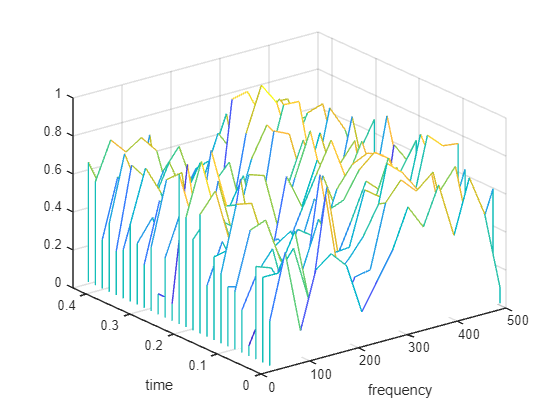

waterfall(f_1(n/2+1:n),t_1,abs(kappa(n/2+1:n,:))')
xlabel("frequency")
ylabel("time")

The above is a waterfall plot and we can see that the frequencies are similar around 0. This is due to the symmetric nature of fft. Discarding the negative frequencies, we can plot another graph that gives us the coherence value kappa

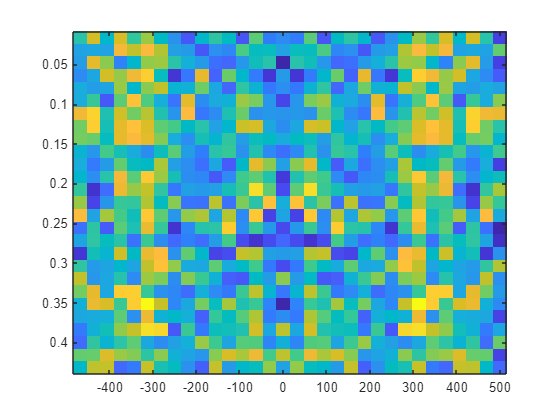

imagesc(f_1,t_1,abs(kappa)')

Now, to compute the coherence of both these, we first need to calculate cross spectrum. A good way to calculate it would be using the xspectrogram function in matlab that would give the cross spectrogram

[s,f,t] = xspectrogram(data_chan_1,data_chan_120,64,32,[],fs,[],"power")

s = 129×152
  231.7876  247.2970   25.5867   78.1918   31.6620    0.9854  175.7023   14.9840   32.5476   17.6970  254.0471  140.3994   14.7100   60.0017  279.1683  125.1940  261.9117    0.2202   17.6725   85.4303    9.8567   76.3847   19.1252   16.2055   11.7596  204.1843  128.3121   90.9599   67.6893   93.4962
  412.5332  455.1915   37.7772  175.6882   90.9111  103.9543  339.1105   47.8018   52.3563   70.3601  469.4524  269.0280   26.5978  220.7688  519.0221  262.1709  481.1410   26.4460   58.8578  158.3836   45.5102  163.4603   47.1676   51.1841   85.2857  385.8321  248.6561  189.3441  117.3896  185.4222
  286.5697  350.7474    8.2263  202.9680  108.3016  197.3148  305.3577   47.2319   18.0434  124.3842  370.2789  230.5682   26.3676  376.2705  408.2172  277.0798  369.2434   58.3481   90.4941  125.7242   79.5064  170.5925   58.6018   83.6615  161.0108  317.8012  215.5718  201.3699   86.7386  184.7302
  167.1812  216.7111   17.3620  202.0007   89.2076  268.9748  257.6657   12.3033   27

f = 129×1
         0
    3.9062
    7.8125
   11.7188
   15.6250
   19.5312
   23.4375
   27.3438
   31.2500
   35.1562


t = 1×152
    0.0320    0.0640    0.0960    0.1280    0.1600    0.1920    0.2240    0.2560    0.2880    0.3200    0.3520    0.3840    0.4160    0.4480    0.4800    0.5120    0.5440    0.5760    0.6080    0.6400    0.6720    0.7040    0.7360    0.7680    0.8000    0.8320    0.8640    0.8960    0.9280    0.9600


We can use this to get the cross spectrogram as well:

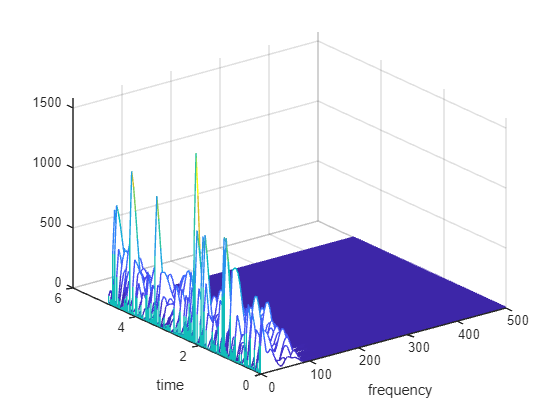

waterfall(f,t,s')
xlabel("frequency")
ylabel("time")

We can use the same function to get the autospectrum as well

[s_1_auto,f_1_auto,t_1_auto] = xspectrogram(data_chan_1,data_chan_1,hamming(64),32,[],fs,"power")

s_1_auto = 129×152
   78.8921  374.0907    2.1975    9.2894   10.3922  178.7973   56.7858    4.6096    6.8253  173.1807  214.6005   49.6994   20.7180    9.3463  165.1843  521.5063  237.5958    0.0033    1.5074   41.7887    1.5764  172.2175    5.1941   32.6748    0.1297  183.4357  212.0965  101.5027  218.6590   50.3470
  128.4648  733.7020    2.6428   25.3195   51.2590  358.0774  112.1694   31.0902    8.7119  336.8430  405.9524  101.4118   40.6329   62.4896  286.4607  973.7376  426.1516   20.1799    8.4274   77.5545   16.2133  316.5242   17.1979   68.6716    3.5899  362.1932  371.9151  190.8927  422.1864   99.3001
   67.5364  691.5395    0.1690   42.6193  127.4155  356.7243  108.2371   86.0990    1.0201  310.9406  345.7125  103.9328   39.3816  176.4949  181.8863  794.1102  305.4396   70.0689   20.2600   61.8805   46.7914  244.4838   34.0913   76.4183   14.9777  344.1171  246.3913  164.6113  376.6559  100.9835
   26.7182  625.2162    1.2570   62.4552  212.0494  347.0430  101.4888  149.53

f_1_auto = 129×1
         0
    3.9062
    7.8125
   11.7188
   15.6250
   19.5312
   23.4375
   27.3438
   31.2500
   35.1562


t_1_auto = 1×152
    0.0320    0.0640    0.0960    0.1280    0.1600    0.1920    0.2240    0.2560    0.2880    0.3200    0.3520    0.3840    0.4160    0.4480    0.4800    0.5120    0.5440    0.5760    0.6080    0.6400    0.6720    0.7040    0.7360    0.7680    0.8000    0.8320    0.8640    0.8960    0.9280    0.9600


[s_120_auto,f_120_auto,t_120_auto] = xspectrogram(data_chan_120,data_chan_120,hamming(64),32,[],fs,"power")

s_120_auto = 129×152
1.0e+03 *

    0.6810    0.1635    0.2979    0.6582    0.0965    0.0000    0.5436    0.0487    0.1552    0.0018    0.3007    0.3966    0.0104    0.3852    0.4718    0.0301    0.2887    0.0147    0.2072    0.1746    0.0616    0.0339    0.0704    0.0080    1.0663    0.2273    0.0776    0.0815    0.0210    0.1736
    1.3247    0.2824    0.5400    1.2191    0.1612    0.0302    1.0252    0.0735    0.3146    0.0147    0.5429    0.7137    0.0174    0.7800    0.9404    0.0706    0.5432    0.0347    0.4111    0.3235    0.1277    0.0844    0.1294    0.0381    2.0261    0.4110    0.1662    0.1878    0.0326    0.3462
    1.2160    0.1779    0.4004    0.9666    0.0921    0.1091    0.8615    0.0259    0.3192    0.0498    0.3966    0.5115    0.0177    0.8022    0.9162    0.0967    0.4464    0.0486    0.4042    0.2554    0.1351    0.1190    0.1007    0.0916    1.7309    0.2935    0.1886    0.2463    0.0200    0.3379
    1.0461    0.0751    0.2398    0.6533    0.0375    0.2085    0

f_120_auto = 129×1
         0
    3.9062
    7.8125
   11.7188
   15.6250
   19.5312
   23.4375
   27.3438
   31.2500
   35.1562


t_120_auto = 1×152
    0.0320    0.0640    0.0960    0.1280    0.1600    0.1920    0.2240    0.2560    0.2880    0.3200    0.3520    0.3840    0.4160    0.4480    0.4800    0.5120    0.5440    0.5760    0.6080    0.6400    0.6720    0.7040    0.7360    0.7680    0.8000    0.8320    0.8640    0.8960    0.9280    0.9600


Drawing the auto spectrogram of both the data channels, we should get a plot similar to the power spectrum

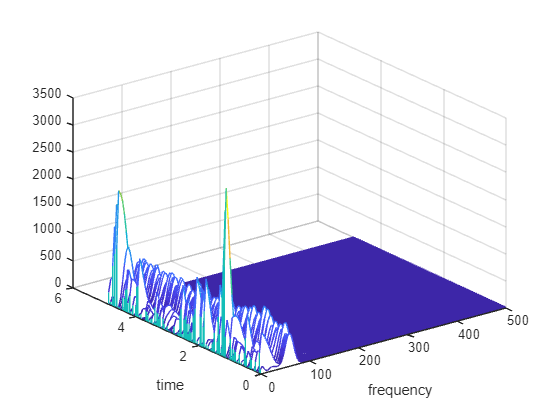

waterfall(f_1_auto,t_1_auto,s_1_auto')
xlabel("frequency")
ylabel("time")

Calculating the same for data channel number 120

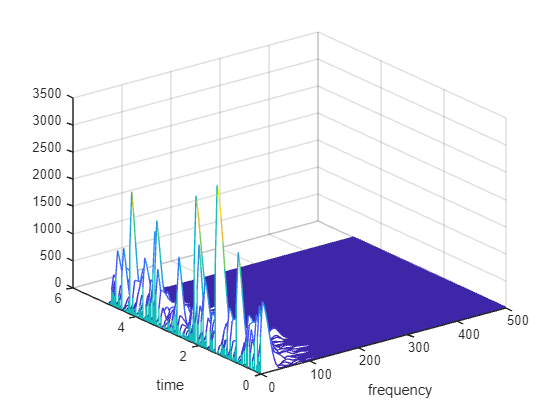

waterfall(f_120_auto,t_120_auto,s_120_auto')
xlabel("frequency")
ylabel("time")

Now, to calculate the values of coherence or kappa, we divide the cross-spectrum with sqrt of both the auto spectrum. It is done as below:

kappa = s./(sqrt(s_120_auto))

kappa = 129×152
    8.8821   19.3414    1.4824    3.0479    3.2237   13.3715    7.5356    2.1470    2.6125   13.1598   14.6493    7.0498    4.5517    3.0572   12.8524   22.8365   15.4141    0.0573    1.2278    6.4644    1.2555   13.1232    2.2791    5.7162    0.3601   13.5438   14.5635   10.0749   14.7871    7.0956
   11.3342   27.0869    1.6257    5.0319    7.1595   18.9229   10.5910    5.5759    2.9516   18.3533   20.1483   10.0703    6.3744    7.9050   16.9252   31.2048   20.6434    4.4922    2.9030    8.8065    4.0266   17.7911    4.1470    8.2868    1.8947   19.0314   19.2851   13.8164   20.5472    9.9649
    8.2181   26.2971    0.4111    6.5283   11.2878   18.8871   10.4037    9.2790    1.0100   17.6335   18.5933   10.1947    6.2755   13.2851   13.4865   28.1800   17.4768    8.3707    4.5011    7.8664    6.8404   15.6360    5.8388    8.7418    3.8701   18.5504   15.6969   12.8301   19.4076   10.0491
    5.1690   25.0043    1.1212    7.9029   14.5619   18.6291   10.0742   12.2285 

kappa = kappa./(sqrt(s_1_auto))

kappa = 129×152
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000 

We can now plot frequency and time against kappa to analyse the coherence between frequencies

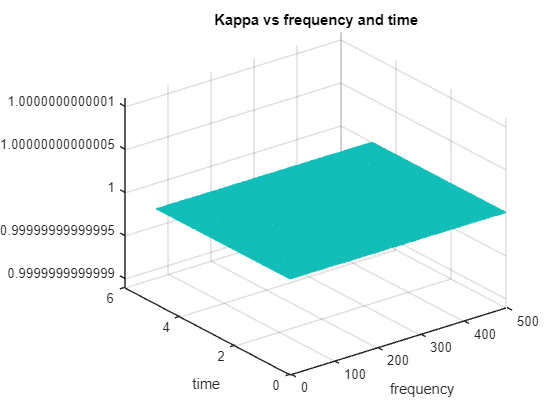

waterfall(f,t,kappa')
xlabel("frequency")
ylabel("time")
title("Kappa vs frequency and time")